# Planning layer for waypoint trajectory generation

% this script tests the waypointPlanning function, which only accepts
% waypoints and the via point velocities and outputs an overall trajectory
waypoint_positions = [
    0 0 0;
    0 0.1 0;
    0 0.2 0;
    0 0.2 0.5;
    0 0.2 0.7
];

waypoint_orientations = [
    quaternion(1,0,0,0);
    quaternion(0,1,0,0);
    quaternion(0,1,0,0);
    quaternion(0,0,1,0);
    quaternion(0,1,0,0);
];

via_point_velocities = [
    0.3;
    0.2;
    0.4;
];


[translation_traj,rotation_traj,linear_velocity,angular_velocity,timesteps]=waypointPlanning(waypoint_positions,waypoint_orientations,via_point_velocities);

## Graph stuff

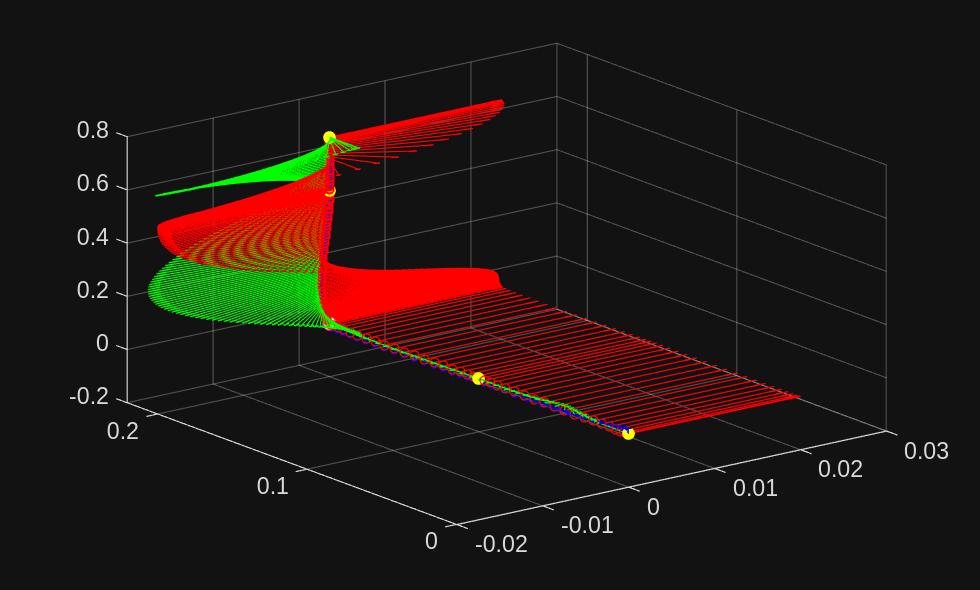

figure = "traj_plot";
scatter3(translation_traj(:,1),translation_traj(:,2),translation_traj(:,3),15,"red");
hold on;
scatter3(waypoint_positions(3,1),waypoint_positions(3,2),waypoint_positions(3,3),40,"magenta","filled");
scatter3(waypoint_positions(:,1),waypoint_positions(:,2),waypoint_positions(:,3),30,"yellow","filled");
for i=[1:size(rotation_traj,1)]
    plot_frame(translation_traj(i,:),rotation_traj(i),0.2);
end
hold off